# Estimation of blood pressure from ECG and PPG signals

## Introduction

Motivation: Why do we need "24h ambulatory blood pressure monitoring"?  

Solutions: what methods do you know?

Your solution: in short your hypotheses and solution

(Note: you insert figures, equations ....)

## Dataset

Data were used from the "PainLess" study of healthy volunteers at the Biomedical Engineering Institute (Kaunas, Lithuania), with approval by the Kaunas Region Biomedical Research Ethics Committee (No. BE-2-24). The total number of participants was 35. 

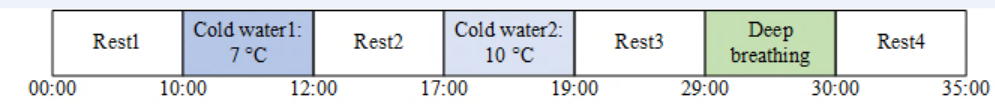

**Fig. 1 Data collection protocol**

Registered biosignals (Fig.2): 1) reference blood pressure waveform - CNAP Monitor (CNSystems, Graz, Austria), sampling rate 100Hz; 2) electrocardiogram (ECG) and photoplehysmogram (PPG) - Nautilus (Biomedical Engineering Institute, Kaunas, Lithuania), sampling rate for ECG - 2000Hz, and 1000Hz for PPG. ECG array contains 3 leads (Lead 1, Lead II, Lead III) in 3xN matrix. PPG array contains 2 channels (IR- infrared and R- red LEDs) in 2xM matrix. 

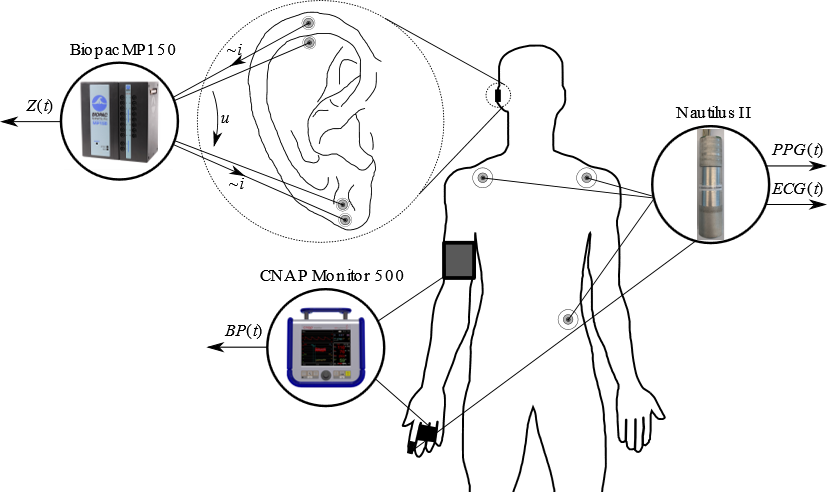

**Fig. 2 Biosignal registration setup**

## Load and visualise the signals

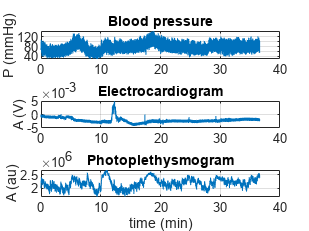

close all

fname='Painless021.mat';
load(fname);

figure
t_bp=(0:length(bp)-1)*1/f_bp;
ax1=subplot(3,1,1);plot(t_bp/60, bp);grid
title('Blood pressure'), ylabel('P (mmHg)')

t_ecg=(0:length(ecg(1,:))-1)*1/f_ecg;
ax2=subplot(3,1,2);plot(t_ecg/60, ecg(1,:));grid
title('Electrocardiogram'), ylabel('A (V)')

t_ppg=(0:length(ppg(1,:))-1)*1/f_ppg;
ax3=subplot(3,1,3);plot(t_ppg/60, ppg(1,:));grid
title('Photoplethysmogram'), ylabel('A (au)'), xlabel('time (min)')
linkaxes([ax1,ax2,ax3],'x')

## Signal Preprocessing

1) Equalize sampling frequencies of all signals (BP, ECG, and PPG) to 500Hz. 

2) Low- and highpass filter ECG and PPG signals: eg., f_co_hp=0.5Hz,  f_co_lp= 17Hz 

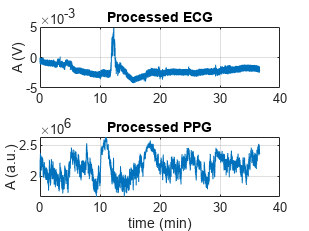

% Equalise sampling rates
Fs=500;

bp=resample(bp,5,1);

ecg = decimate(ecg(1,:),4); % Decrease sampling rate
t_ecg=(0:length(ecg)-1)*1/Fs;
ppg = decimate(ppg(1,:),2); % Decrease sampling rate

figure
ax1=subplot(2,1,1);plot(t_ecg/60, ecg),grid
title('Processed ECG'), ylabel('A (V)')

ax2=subplot(2,1,2);plot(t_ecg/60, ppg),grid
title('Processed PPG'), ylabel('A (a.u.)')
xlabel('time (min)')
linkaxes([ax1,ax2],'x')

clear ax1 ax2;

% Filter ECG and PPG signals



## Target Feature Extraction

Extract and visualise: systolic (SBP), dyastolic (DBP) and mean blood pressures (MBP)

% Extract systolic, dyastolic and mean blood pressures




## Input Feature Extraction

Extract and visualise the folowing features: 

1) Pulse Arrival Time (PAT)

2) Pulse intensity ratio (PIR)

3) Heart rate (HR)  

% Extract PAT


## Train regression model

Start with [linear regression](https://se.mathworks.com/help/stats/what-is-linear-regression.html)

Terms:

    Predictor variable X (matrix)

    Response variable y (vector)

Use fitlm for training the model [`mdl = fitlm(X,y)`](https://se.mathworks.com/help/stats/fitlm.html#d123e354383)

% Regress PAT against SBP


## Evaluate regression model 

To examine the categorical variable as a group of indicator variables, use the object function [`anova`](https://se.mathworks.com/help/stats/linearmodel.anova.html). This function returns analysis of variance (ANOVA) statistics of the model.

...

## **Predict Responses to New Data**

Predict responses to the test data set by using the fitted model `newMdl2` and the object function [`predict`](https://se.mathworks.com/help/stats/linearmodel.predict.html) 

...